# Lunes 15 noviembre

Capítulo 1: Introduccion a Simulink

Estudiante: Victor Asanza

Materia: Simulación de Sistemas Eléctricos

Dataset: [https://ieee-dataport.org/open-access/data-server-energy-consumption-dtaset](https://ieee-dataport.org/open-access/data-server-energy-consumption-dtaset)

Frecuencia de muestreo: 4Hz

**Paso1: Cargar un archivo .mat con frecuencia de muestreo de 1sample / 15min**

**Data (451x9), donde 451x15min=6765min/60min=112.75horas/24=4.69dias**

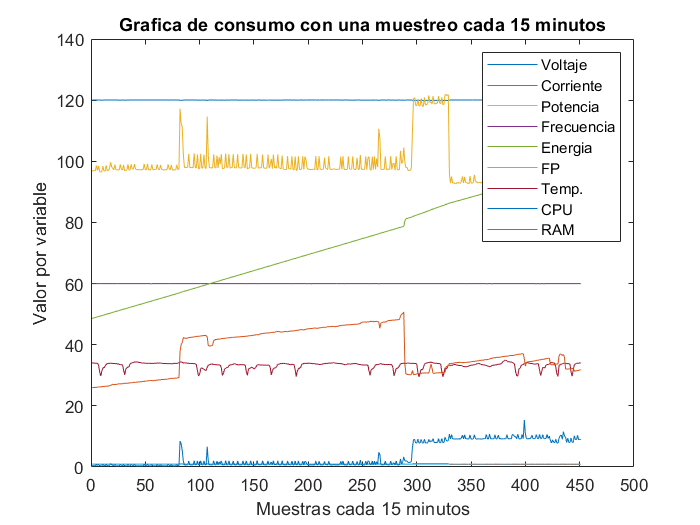

clear;%borra el worskpace
clc;%borra el comand windiw
path=fullfile('./datamean.mat');
data=load(path);
data=struct2cell(data);
data=data{1,1};%table
plot(data);%datos originales
title('Grafica de consumo con una muestreo cada 15 minutos');
legend('Voltaje','Corriente','Potencia','Frecuencia','Energia','FP','Temp.','CPU','RAM');

xlabel('Muestras cada 15 minutos');
ylabel('Valor por variable');

**Ejemplo 1: Separar las variables**

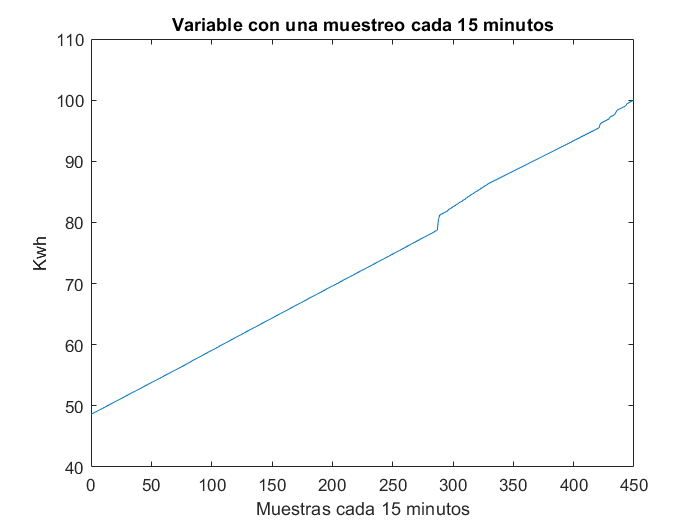

Time=(0:1:length(data)-1)'; %Vector de tiempo
Voltaje=[Time data(:,1)];
Corriente=[Time data(:,2)];
Potencia=[Time data(:,3)];
Frecuencia=[Time data(:,4)];
Energia=[Time data(:,5)];
FP=[Time data(:,6)];
Temp=[Time data(:,7)];
CPU=[Time data(:,8)];
RAM=[Time data(:,9)];


plot(Energia(:,1),Energia(:,2));%datos originales
title('Variable con una muestreo cada 15 minutos');
%legend('Voltaje','Corriente','Potencia','Frecuencia','Energia','FP','Temp.','CPU','RAM');
xlabel('Muestras cada 15 minutos');
ylabel('Kwh');

**Ejemplo 2: Save CSV file**

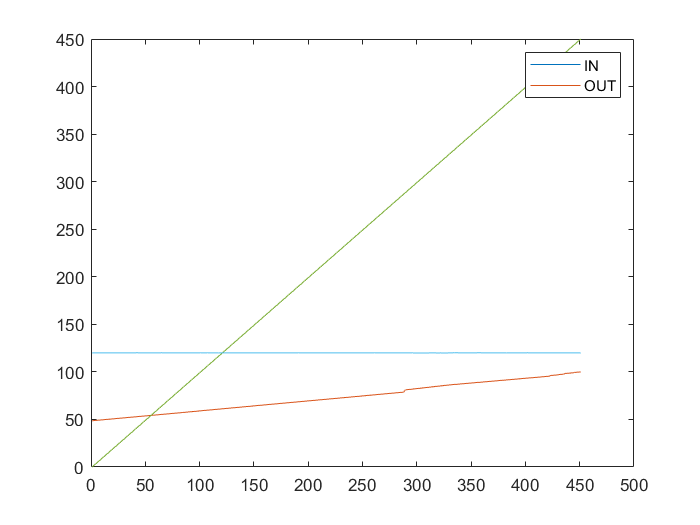

IN=Voltaje(:,1);
OUT=Voltaje(:,2);

plot(IN);
hold on
plot(OUT);
legend('IN','OUT');

%save('Energia.csv',"Energia");

**Ejemplo 3: Modelado**

ident